temp2 =      2
     2
     2
     1
     1
     3
     1
     0
     2
     1


postition = 6

temp2 =      2
     0
     0
     1
     1
     1
     1
     2
     2
     3


postition = 10

temp2 =      0
     1
     2
     1
     0
     1
     3
     1
     2
     1


postition = 7

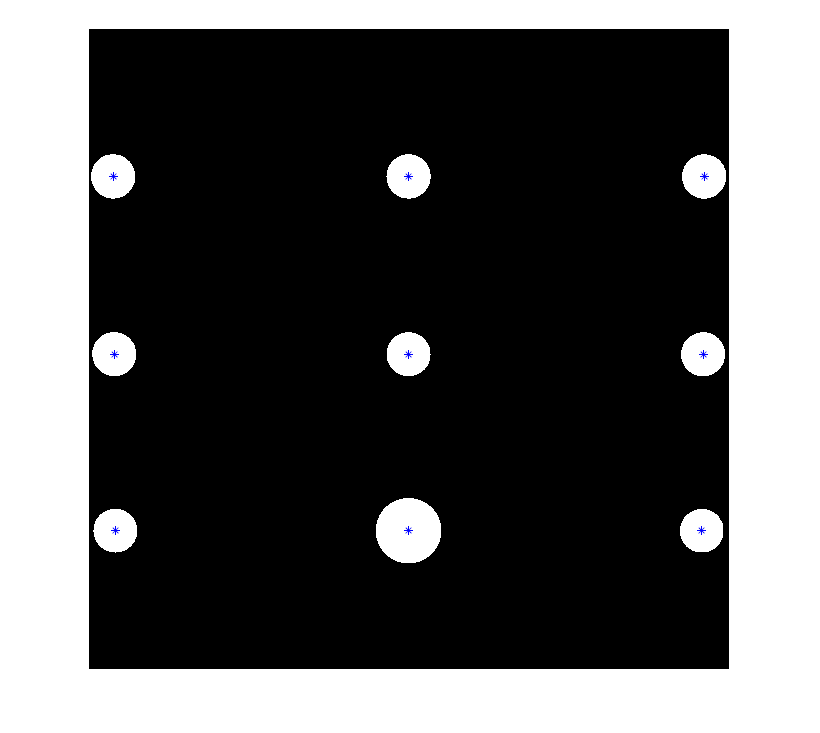

a = 1×2 cell array
    {2×3 double}    {2×3 double}


% sim = coppeliaRobot();
% ---
init_image = imread("init_image2.jpg");
dest_image = imread("init_image3.jpg");
% ---

a = EGB339_21S2_19(sim, init_image, dest_image)

init_xy=a{1}

init_xy =   274.7315  288.1263  335.2406
  327.7212  452.2193  196.2684


dest_xy=a{2}

dest_xy =   254.1876  214.9933  192.1290
  102.6054  213.2467  467.5011


## ROBOT ARM

cylinderPos = [init_xy(1,1) init_xy(2,1); init_xy(1,2) init_xy(2,2); init_xy(1,3) init_xy(2,3)]

cylinderPos =   274.7315  327.7212
  288.1263  452.2193
  335.2406  196.2684


setCylinderPosition(sim, cylinderPos);

xy =     0.2747    0.3277
    0.2881    0.4522
    0.3352    0.1963


q0 = [0 0 0 0 0];
% ---


setJointPositions(sim, q0);
pause(2);
for i = 1:3
    % Reach to initial position
    init_xy(:,i)
    q_new = reach(sim, init_xy(1,i), init_xy(2,i));
    setSuctionCup(sim, 1);
    
    % Back to origin
    q_current = getJointPositions(sim);
    q_mid = jtraj(q_current, q0, 10);
    for q=q_mid'
        setJointPositions(sim, q);
    end
    
    % Reach to destination position
    dest_xy(:,i)
    reach(sim, dest_xy(1,i), dest_xy(2,i));
    setSuctionCup(sim, 0);
    
    % Back to origin
    q_current = getJointPositions(sim);
    q_mid = jtraj(q_current, q0, 10);
    for q=q_mid'
        setJointPositions(sim, q);
    end
end

ans =   274.7315
  327.7212


ans =   254.1876
  102.6054


ans =   288.1263
  452.2193


ans =   214.9933
  213.2467


ans =   335.2406
  196.2684


ans =   192.1290
  467.5011
